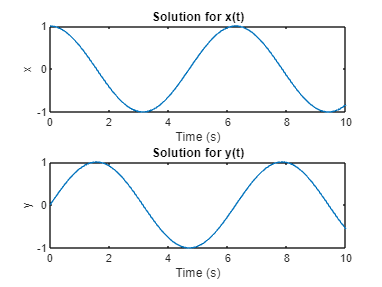

A = [0 -1; 1 0];
T = 10;
N = 100;
Z0 = [1; 0];

[t, x, y] = IEMSolver(A, Z0, T, N);

figure;
subplot(2, 1, 1)
plot(t, x, "-", "DisplayName", "Solution");
xlabel("Time (s)")
ylabel("x")
title("Solution for x(t)")

subplot(2, 1, 2)
plot(t, y, "-", "DisplayName", "Solution");
xlabel("Time (s)")
ylabel("y")
title("Solution for y(t)")

function [t, x, y] = IEMSolver(A, Z0, T, N)
    dt = T / N;
    t = 0:dt:T;
    sol = NaN(2, length(t));
    sol(:, 1) = Z0;
    for n = 2:length(t)
        sol(:, n) = sol(:, n - 1) + A * dt * sol(:, n - 1);
        sol(:, n) = sol(:, n - 1) + (dt / 2) * A * (sol(:, n - 1) + sol(:, n));
    end
    x = sol(1, :);
    y = sol(2, :);
end